f = @(x) (x+1).^2.*cos((2*x+1)./(x-4.3));
I = integral(f,0,4,'abstol',1e-14,'reltol',1e-14);  % 'exact' value

We perform the integration and show the nodes selected underneath the curve. 

[Q,t] = intadapt(f,0,4,0.001);
fplot(f,[0 4],2000,'k'), hold on
stem(t,f(t),'.-')
num_nodes = length(t)

num_nodes =     69


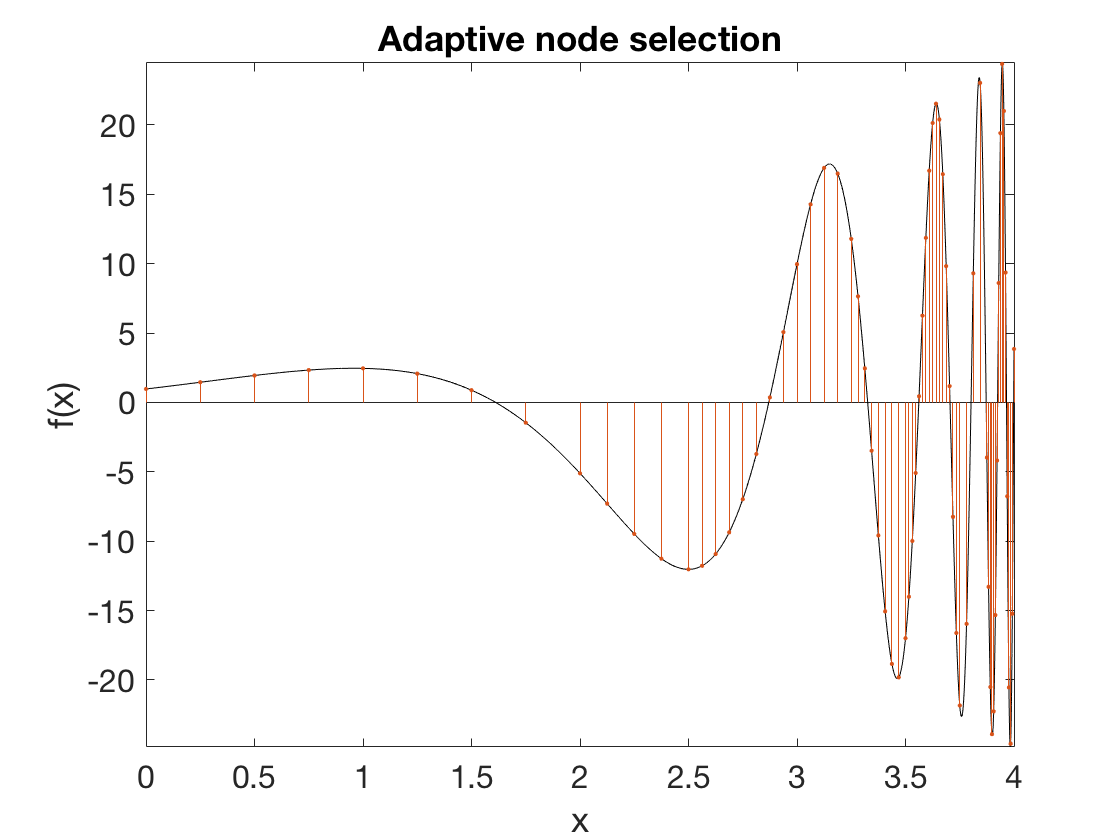

title('Adaptive node selection')    % ignore this line
xlabel('x'), ylabel('f(x)')    % ignore this line

The error turns out to be a bit more than we requested. It's only an estimate, not a guarantee.

err = I - Q

err =   -0.022002813037628


Let's see how the number of integrand evaluations and the error vary with the requested tolerance.

tol_ = 10.^(-4:-1:-14)';
err_ = 0*tol_;
num_ = 0*tol_;

for i = 1:length(tol_)
    [Q,t] = intadapt(f,0,4,tol_(i));
    err_(i) = I - Q;
    num_(i) = length(t);
end

table(tol_,err_,num_,'variablenames',{'tol','error','f_evals'})

ans = 11×3 table
     tol              error            f_evals
    ______    _____________________    _______

    0.0001    -0.000419468817776103      113  
     1e-05     4.78976625362115e-05      181  
     1e-06     6.31438384779415e-06      297  
     1e-07    -6.63924977661878e-07      489  
     1e-08     7.18080688244527e-08      757  
     1e-09      1.2652384473455e-08     1193  
     1e-10    -8.44127434618258e-10     2009  
     1e-11     2.61257682154792e-11     3157  
     1e-12     4.04449806978846e-11     4797  
     1e-13    -1.93844940099552e-12     7997  
     1e-14     1.61648472385423e-13    12609  


As you can see, even though the errors are not less than the estimates, the two columns decrease in tandem. If we consider now the convergence not in $h$ (which is poorly defined) but in the number of nodes actually chosen, we come close to the fourth order accuracy of the underlying Simpson scheme.

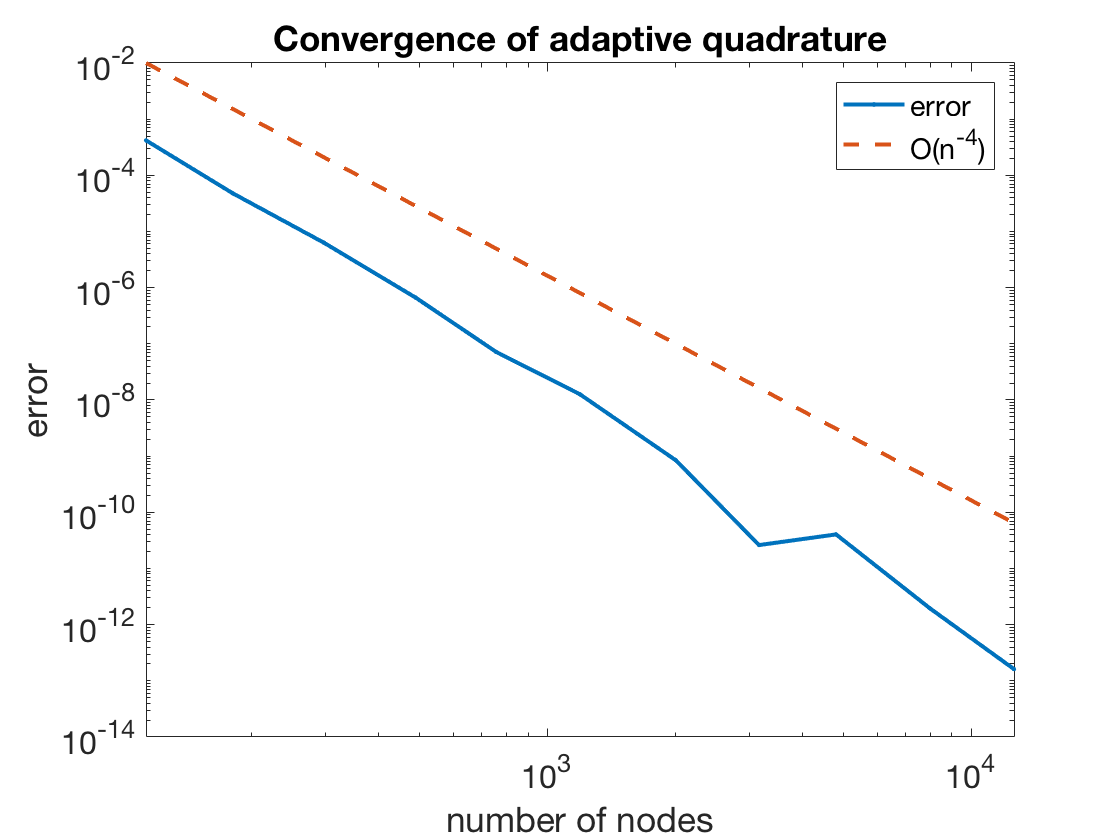

clf,  loglog(num_,abs(err_),'.-')
hold on
loglog(num_,0.01*(num_/num_(1)).^(-4),'--')
title('Convergence of adaptive quadrature')   % ignore this line
xlabel('number of nodes'),  ylabel('error')   % ignore this line
legend('error','O(n^{-4})')   % ignore this line
xlim(num_([1 end]))   % ignore this line